clear;clc;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%引入损耗%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('Loss_particular.mat');
FSPL_M = A_M

FSPL_M = 136.5266

FSPL_E = A_E

FSPL_E =   270.7026
  275.1395
  281.1601
  284.6820
  287.1807


load('Loss_frequency.mat');
FSPL_M_f = A_M_f

FSPL_M_f =   133.9853  134.0142  134.0430  134.0717  134.1003  134.1289  134.1573  134.1857  134.2139  134.2421  134.2701  134.2981  134.3260  134.3538  134.3815  134.4092  134.4367  134.4641  134.4915  134.5188  134.5460  134.5731  134.6001  134.6270  134.6539  134.6807  134.7074  134.7340  134.7605  134.7869  134.8133  134.8396  134.8658  134.8919  134.9180  134.9440  134.9698  134.9957  135.0214  135.0471  135.0727  135.0982  135.1236  135.1490  135.1743  135.1995  135.2246  135.2497  135.2747  135.2996


FSPL_E_f = A_E_f

FSPL_E_f =   270.7026  270.7265  270.7505  270.7745  270.7985  270.8224  270.8464  270.8703  270.8943  270.9182  270.9421  270.9660  270.9899  271.0138  271.0377  271.0615  271.0854  271.1092  271.1331  271.1569  271.1807  271.2046  271.2284  271.2522  271.2760  271.2998  271.3235  271.3473  271.3711  271.3948  271.4185  271.4423  271.4660  271.4897  271.5134  271.5371  271.5608  271.5845  271.6082  271.6319  271.6555  271.6792  271.7029  271.7265  271.7501  271.7738  271.7974  271.8210  271.8446  271.8682
  275.1395  275.1635  275.1875  275.2115  275.2354  275.2594  275.2834  275.3073  275.3312  275.3551  275.3791  275.4030  275.4269  275.4508  275.4746  275.4985  275.5224  275.5462  275.5701  275.5939  275.6177  275.6415  275.6653  275.6892  275.7129  275.7367  275.7605  275.7843  275.8080  275.8318  275.8555  275.8793  275.9030  275.9267  275.9504  275.9741  275.9978  276.0215  276.0452  276.0689  276.0925  276.1162  276.1398  276.1635  276.1871  276.2107  276.2344  276.2580  276.28

# **一、火星着陆器-火星轨道器通信链路**  

**火星着陆器向火星轨道器通信：**

轨道高度d是400km，发射数字信号的比特率是250 Mbit/s，

工作频率是400MHz，发射功率是43dBm(20W)。发射天线的直径是80cm。

若所需的Eb/N0是8dB，接收系统的噪声温度是150K，玻尔兹曼常数k=1.38e^(-23)，

请确定所需的接收天线的尺寸大小。

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%条件设置%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_M = 400;% 轨道高度，单位：km
Eb_N0 = 8;% 单位比特能量/噪声功率，单位：db
freq = 0.4;% 频率，单位：MHz
T_s = 150;% 噪声温度，单位：K，对于UHF波段
P_t = 43;%发射功率,单位：dBm
k = 1.38e-23;% 玻尔兹曼常数
D_t = 0.8;% 发射天线的直径
R = 250e6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Dr_0=getDr(T_s,k,Eb_N0,D_t,freq,FSPL_M,P_t,R)

Dr_0 = 0.3781

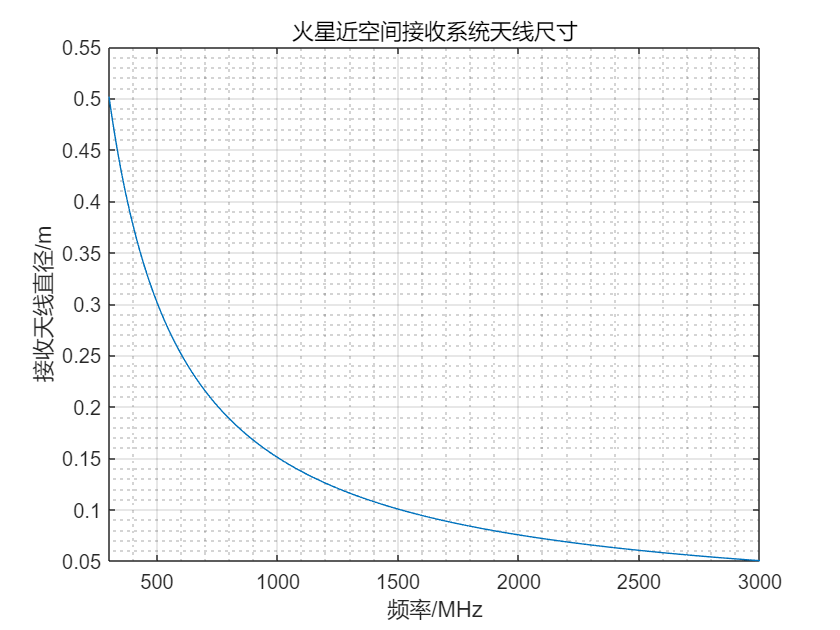

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%扫频%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f = 0.3: 0.001 : 3;
Dr_f = getDr(T_s,k,Eb_N0,D_t,f,FSPL_M_f,P_t,R);
figure();
plot(f.*1000,Dr_f);
xlim([300,3000])
xlabel('频率/MHz');
ylabel('接收天线直径/m');
title('火星近空间接收系统天线尺寸');
grid on;grid minor;

# **二、火星轨道器-地球站通信链路**  

发射功率、通信速率、信噪比、接收天线尺寸之间存在权衡

### **火星向地球通信：**

轨道高度d是0.6-4亿km，发射数字信号的比特率是2.5 Mbit/s，

工作频率是8GHz，发射功率是dBm(200W)。发射天线的直径是3m。

若所需的Eb/N0是12dB，接收系统的噪声温度是50K，玻尔兹曼常数k=1.38e^(-23)，

请确定所需的接收天线的尺寸大小。

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%条件设置%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d_E=[0.6,1,2,3,4];
d_E=1e8*d_E;% 轨道高度，单位：km
Eb_N0 = 12;% 单位比特能量/噪声功率，单位：db
freq = 8;% 频率，单位：MHz
T_s = 60;% 噪声温度，单位：K，对于UHF波段
P_t = 53;%发射功率,单位：dBm
k = 1.38e-23;% 玻尔兹曼常数
D_t = 3;% 发射天线的直径
R = 2.5e6;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%计算%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Dr_0=zeros(length(d_E),1);
for i=1:length(d_E)
    Dr_0(i)=getDr(T_s,k,Eb_N0,D_t,freq,FSPL_E(i),P_t,R);
end
Dr_0

Dr_0 =    31.5793
   52.6321
  105.2642
  157.8963
  210.5285



for i=1:length(d_E)
    Dr_0(i)=getDr(T_s,k,Eb_N0,D_t,freq,FSPL_E(i),63,R);
end
Dr_0

Dr_0 =     9.9862
   16.6437
   33.2875
   49.9312
   66.5749


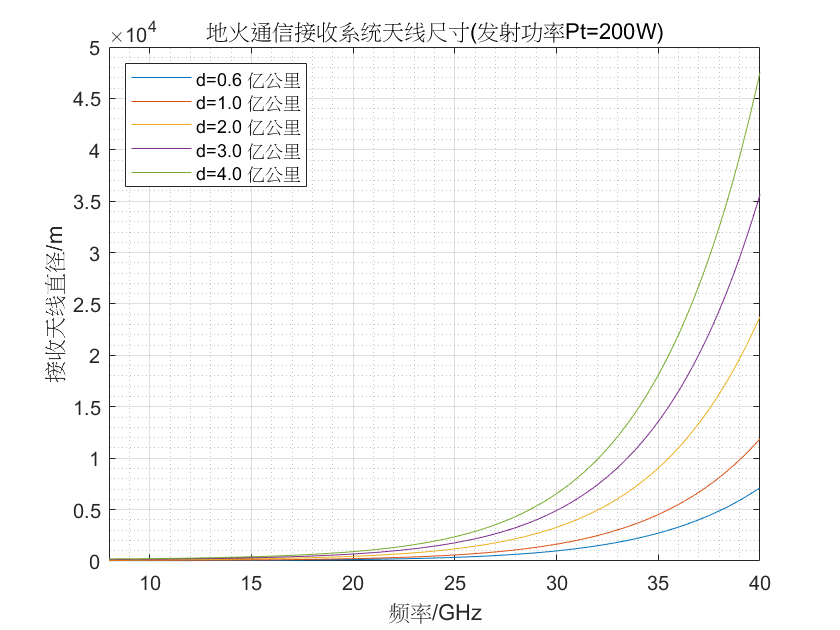

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%扫频%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f=8:0.01:40;%频率，单位：GHz
Dr_f=zeros(length(d_E),length(f));
figure();
for i=1:length(d_E)
    Dr_f(i,:) = getDr(T_s,k,Eb_N0,D_t,f,FSPL_E_f(i,:),P_t,R);
    plot(f,Dr_f(i,:));
    hold on;
end
xlim([8,40])
xlabel('频率/GHz');
ylabel('接收天线直径/m');
title('地火通信接收系统天线尺寸(发射功率Pt=200W)');
grid on;grid minor;
lgd=legend(sprintf('d=%.1f 亿公里',d_E(1)/1e8),sprintf('d=%.1f 亿公里',d_E(2)/1e8),...
    sprintf('d=%.1f 亿公里',d_E(3)/1e8),sprintf('d=%.1f 亿公里',d_E(4)/1e8),...
    sprintf('d=%.1f 亿公里',d_E(5)/1e8));
lgd.Location="northwest";

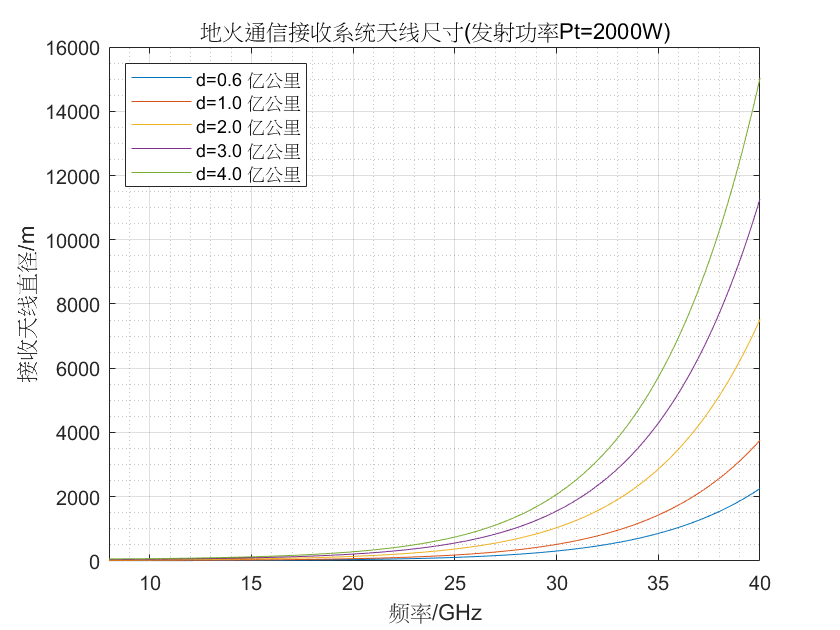

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%扫频%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
f=8:0.01:40;%频率，单位：GHz
Dr_f=zeros(length(d_E),length(f));
figure();
for i=1:length(d_E)
    Dr_f(i,:) = getDr(T_s,k,Eb_N0,D_t,f,FSPL_E_f(i,:),63,R);
    plot(f,Dr_f(i,:));
    hold on;
end
xlim([8,40])
xlabel('频率/GHz');
ylabel('接收天线直径/m');
title('地火通信接收系统天线尺寸(发射功率Pt=2000W)');
grid on;grid minor;
lgd=legend(sprintf('d=%.1f 亿公里',d_E(1)/1e8),sprintf('d=%.1f 亿公里',d_E(2)/1e8),...
    sprintf('d=%.1f 亿公里',d_E(3)/1e8),sprintf('d=%.1f 亿公里',d_E(4)/1e8),...
    sprintf('d=%.1f 亿公里',d_E(5)/1e8));
lgd.Location="northwest";

function D_r=getDr(T_s,k,Eb_N0,D_t,freq,FSPL,P_t,R)
N0 = k.*T_s;
E_b = Eb_N0.*N0;
P_r = 10*log10((E_b.*R)*1000);%接收功率
L_M_max = P_t - P_r;
G_t = 18 + 20.*log10(D_t)+20.*log10(freq);
G_r = FSPL - G_t - L_M_max;
D_r = G_r - 20.*log10(freq)-18;
D_r = 10.^(D_r./20);
end